"Synthetic Data Generator" by Kambadur Ananthamurthy

This code uses real dF/F data, populates a library of calcium events, and then creates a synthetic dataset based on the control parameters.

Here is a list of functions or other scripts called within this main script:

- setupSyntheticDataParameters.m

- findConsecutiveOnes.m

- syntheticDataMaker.m

- generateNoise.m

- selectFrameIndex.m

- plotdFbyF.m

- getPSTH.m

Please ensure that you have acess to all of them before proceeding.

tic
close all
clear

addpath(genpath('/Users/ananth/Documents/MATLAB/CustomFunctions')) % my custom functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis')) % Additional functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis/Suite2P-ananth'))


## Operations

This section provides some operational controls.

%ops0.fig             = 1;
ops0.saveData        = 0;

figureDetails = compileFigureDetails(16, 2, 10, 0.5, 'jet'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
%ops0.onlyProbeTrials = 0

## Real Dataset Details

Here, one must provide details of the real dataset to be referenced while making the synthetic data. The code uses some of these parameters to locate the file containing the real dF/F data, while the other parameters are important for functions and plotting. The structure of this section is directly as is required for the Suite-2P analysis pipeline.

It is crucial to use dF/F values rather than the raw fluorescence traces, since only then can the different calcium events be comparable.

make_db

fprintf('Reference Dataset - %s_%i_%i | Date: %s\n', db.mouseName, ...
    db.sessionType, ...
    db.session, ...
    db.date)

Reference Dataset - M26_5_4 | Date: 20180514


## Load dF/F

We then load the real processed data based on the reference dataset.

saveDirec = '/Users/ananth/Desktop/Work/Analysis/Imaging/';
saveFolder = [saveDirec db.mouseName '/' db.date '/'];

%Load processed data (processed dfbf for dataset/session)
realProcessedData = load([saveFolder db.mouseName '_' db.date '.mat']);
nCells = size(realProcessedData.dfbf, 1);
nTrials = size(realProcessedData.dfbf, 2);
nFrames = size(realProcessedData.dfbf, 3);
fprintf('Total cells: %i\n', nCells)

Total cells: 135


## Synthetic Data Control Parameters

Here, one must provide all the control parameters required to generate the synthetic data. These can be found in a header-like file called setupSyntheticDataParameters.m. This sort of implementation ensures minimal (if any) change to this main script, while changing parameters.

setupSyntheticDataParameters

## Curate Calcium Event Library

This next section of code ensures that we have a working library of calcium events.

%Cell specific curation of the calcium event library
%Check to see if the library exits
if isfile([saveFolder db.mouseName '_' db.date '_eventLibrary_2D.mat'])
    disp('Loading existing event library ...')
    load([saveFolder db.mouseName '_' db.date '_eventLibrary_2D.mat'])
    disp('... done!')
else
    %Use real 2D data
    cellMean = zeros(nCells, 1);
    cellStddev = zeros(nCells, 1);
    binaryData = zeros(nCells, 1);
    
    %2D
    disp('Basic scan for calcium events ...')
    for cell = 1:nCells
        sampledTrial = squeeze(realProcessedData.dfbf_2D(cell, :));
        cellMean(cell) = mean(sampledTrial);
        cellStddev(cell) = std(sampledTrial);
        binaryData(find(sampledTrial > (cellMean(cell) + 2*cellStddev(cell))), 1) = 1; %multiplier = 1
        [nEvents, StartIndices, Lengths] = findConsecutiveOnes(binaryData);
        eventLibrary_2D(cell).nEvents = nEvents;
        eventLibrary_2D(cell).eventStartIndices = StartIndices;
        eventLibrary_2D(cell).eventLengths = Lengths;
        
        clear binaryData
        clear Events
        clear StartIndices
        clear Lengths
    end
    disp('... library curated!')
end

Loading existing event library ...


... done!


## Make Synthetic Data

This is business end. We call the syntheticDataMaker function with the control parameters passed in as arguments.

sdo = syntheticDataMaker(db, realProcessedData.dfbf_2D, eventLibrary_2D, sdcp);

Creating synthetic data ...
... Number of Putative Time Cells: 67
... done!


## Plotting the Synthetic Dataset

We can now visualize the synthetic dataset along with checks to ensure the control parameters are working as expected

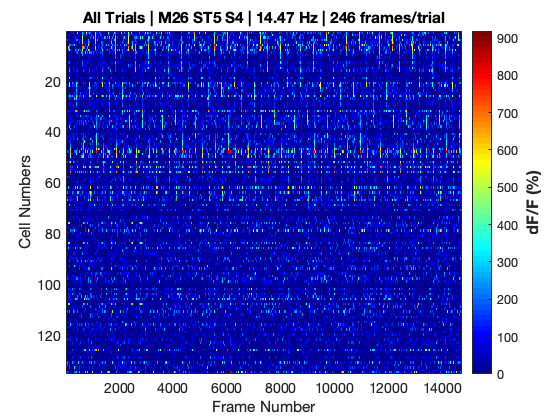

% All trials
figure(1)
clf
plotdFbyF(db, sdo.syntheticDATA_2D, 'All Trials', 'Frame Number', 'Cell Numbers', figureDetails, 0)
colormap(figureDetails.colorMap)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)], ...
    '-djpeg')

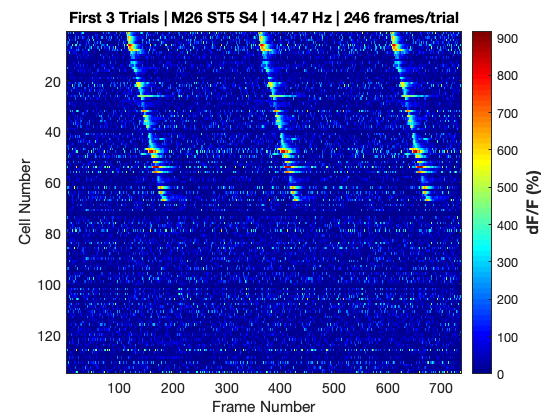

% Only first 3 trials
figure(2)
clf
plotdFbyF(db, sdo.syntheticDATA_2D(:,1:(3*db.nFrames)), 'First 3 Trials', 'Frame Number', 'Cell Number', figureDetails, 0)
colormap(figureDetails.colorMap)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData_first3trials_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)], ...
    '-djpeg')

## Quality metric (Q)

Next, we develop a quality metric "Q', to assign a reliability score to every cell in the synthetic dataset.


$$Q=\frac{\text{Hit}\text{ }\text{Trial}\text{ }\text{Percent}\ast \text{Event}\text{ }\text{Amplification}\text{ }\text{Factor}}{\left(\frac{\left(\mathrm{Actual Event Width Max +Actual Event Width Min}\right)}{2}+\text{ }\text{Imprecision}\right)\ast \text{Noise}\text{ }\text{Percent}}$$


Here, the Hit Trial Percent and the Actual Event Widths are cell specific, while the other controls are fixed for every cell (specified as synthetic data control parameters).

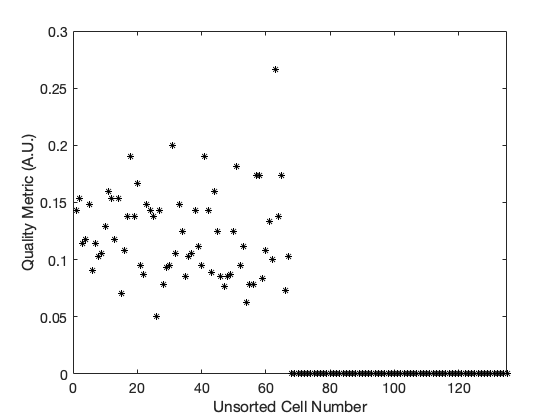

sdo.Q = zeros(nCells, 1);
for cell = 1:nCells
    sdo.Q(cell) = (sdo.hitTrialPercent(cell) * sdcp.eventAmplificationFactor)/((((sdo.actualEventWidth(cell, 1) + sdo.actualEventWidth(cell, 2))/2) + sdcp.imprecisionFWHM) * sdcp.noisePercent);
end
figure(3)
clf
plot(sdo.Q, 'k*')
xlim([0 nCells])
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Quality Metric (A.U.)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData_Q_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)], ...
    '-djpeg')

## Time Vector

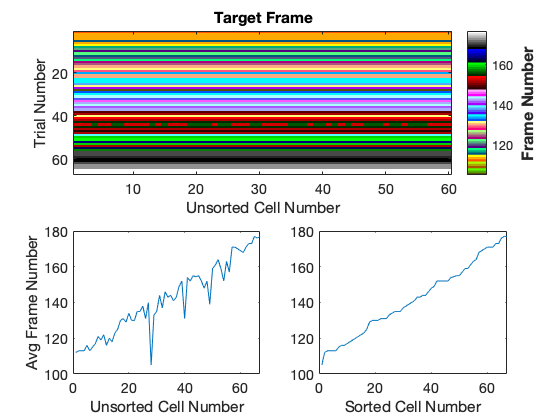

figure(4)
clf
subplot(2,2,1:2)
imagesc(sdo.frameIndex(sdo.ptcList, :))
z = colorbar;
ylabel(z,'Frame Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
colormap('colorcube')
title('Target Frame', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Trial Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(2,2,3)
plot(mean(sdo.frameIndex(sdo.ptcList, :),2))
xlim([0 length(sdo.ptcList)])
%ylim([0 db.nFrames])
% title('Target Frame', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Avg Frame Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(2,2,4)
plot(sort(mean(sdo.frameIndex(sdo.ptcList, :),2)))
xlim([0 length(sdo.ptcList)])
%ylim([0 db.nFrames])
% title('Target Frame', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
xlabel('Sorted Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% ylabel('Avg Frame Number', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData_frameIndex_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)], ...
    '-djpeg')

## Check - Percent Time Cells, Percent Hit Trials, Event Amplification Factor

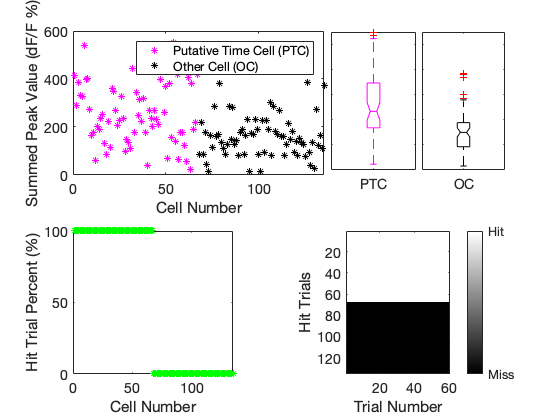

sdtc_peaks = nan(nCells, nTrials); % Putative Time Cells
sdoc_peaks = nan(nCells, nTrials); % Other Cells
for cell = 1:nCells
        for trial = 1:nTrials
            if ismember(cell, sdo.ptcList)
                sdtc_peaks(cell, trial) = max(sdo.syntheticDATA(cell, trial, :));
            else
                sdoc_peaks(cell, trial) = max(sdo.syntheticDATA(cell, trial, :));
            end
        end
end
X1 = sum(sdtc_peaks, 2);
X2 = sum(sdoc_peaks, 2);

figure(5)
clf
subplot(2,5,1:3)
plot(X1, 'm*')
hold on
plot(X2, 'k*')
hold off
if length(X1) > length(X2)
    xlim([0 length(X1)])
else
    xlim([0 length(X2)])
end
% title('Putative Time Cells vs Other Cells', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
xlabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Summed Peak Value (dF/F %)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
legend('Putative Time Cell (PTC)', 'Other Cell (OC)')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(2,5,4)
boxplot(X1, ...
    'Notch','on', ...
    'Labels',{'PTC'}, ...
    'Whisker', 1, ...
    'Color', 'm')
ylim([0 max(X1)])
set(gca,'YTick',0:100:max(X1))
set(gca,'YTickLabel',[])
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(2,5,5)
boxplot(X2, ...
    'Notch','on', ...
    'Labels',{'OC'}, ...
    'Whisker', 1, ...
    'Color', 'k')
ylim([0 max(X1)])
set(gca,'YTick',0:100:max(X1))
set(gca,'YTickLabel',[])
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(2,5,6:7)
plot(sdo.hitTrialPercent, 'g*')
xlim([0 nCells])
ylim([0 100])
xlabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Hit Trial Percent (%)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(2,5,9:10)
imagesc(sdo.hitTrials)
z = colorbar;
z.Ticks = [0, 1];
z.TickLabels = {'Miss', 'Hit'};
colormap('gray')
xlabel('Trial Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Hit Trials', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData_trialSummedPeaks_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)], ...
    '-djpeg')

## Check - Event Width (Exclusively for Putative Time Cells)

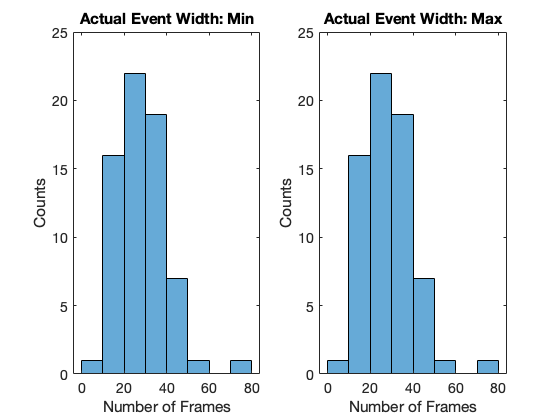

sdo.actualEventWidth(sdo.actualEventWidth == 0) = nan; % Ignore cases without an event
figure(6)
clf
subplot(1,2,1)
histogram(sdo.actualEventWidth(:,1)); % Min
title('Actual Event Width: Min', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Number of Frames', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Counts', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(1,2,2)
histogram(sdo.actualEventWidth(:,2)); % Max
title('Actual Event Width: Max', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Number of Frames', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Counts', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData_actualEventWidth_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)], ...
    '-djpeg')

## Check - ImprecisionFWHM

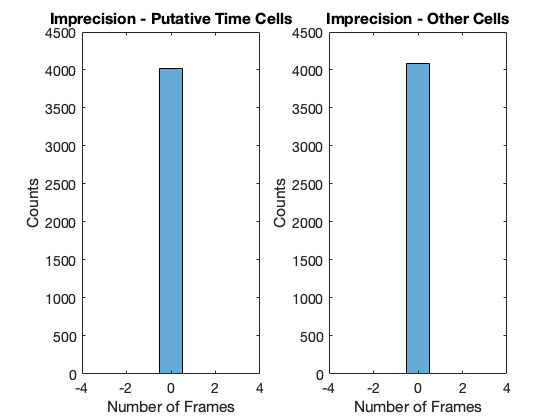

pad_ptc = sdo.pad(sdo.ptcList,:); % Putative Time Cells
pad_oc = sdo.pad(sdo.ocList,:); % Other Cells

figure(7)
clf
subplot(1,2,1)
histogram(pad_ptc)
if sdcp.imprecisionFWHM ~= 0
    xlim([-1*(ceil(sdcp.imprecisionFWHM/2)) floor(sdcp.imprecisionFWHM/2)])
end
title('Imprecision - Putative Time Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Number of Frames', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Counts', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(1,2,2)
histogram(pad_oc)
if sdcp.imprecisionFWHM ~= 0
    xlim([-1*(ceil(sdcp.imprecisionFWHM/2)) floor(sdcp.imprecisionFWHM/2)])
end
title('Imprecision - Other Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Number of Frames', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Counts', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData_imprecision_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)], ...
    '-djpeg')

## Check - Noise

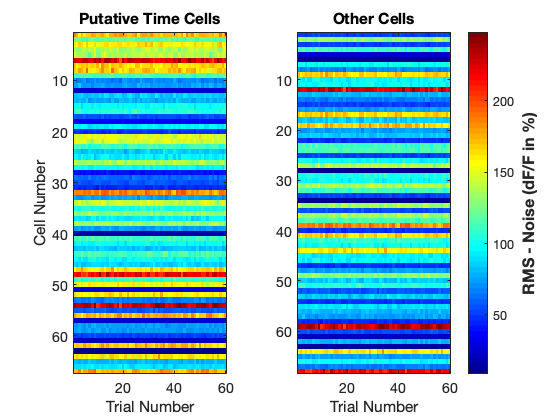

nctc = sdo.noiseComponent(sdo.ptcList, :, :); % Putative Time Cells
ncoc = sdo.noiseComponent(sdo.ocList, :, :); % Other Cells

rms_ptc = zeros(length(sdo.ptcList), nTrials); % Putative Time Cells
rms_oc = zeros(length(sdo.ocList), nTrials); % Other Cells

for cell = 1:size(nctc, 1)
    for trial = 1:size(nctc, 2)
        rms_ptc(cell, trial) = rms(nctc(cell, trial, :), 3);
    end
end

for cell = 1:size(ncoc, 1)
    for trial = 1:size(ncoc, 2)
        rms_oc(cell, trial) = rms(ncoc(cell, trial, :), 3);
    end
end

figure(8);
clf
subplot(1,8,1:3)
imagesc(rms_ptc.*100)
%colorbar
colormap(figureDetails.colorMap)
% ylabel(z,'RMS - dF/F (%)', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
title('Putative Time Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Trial Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(1,8,5:8)
imagesc(rms_oc.*100)
colorbar
colormap(figureDetails.colorMap)
z = colorbar;
ylabel(z,'RMS - Noise (dF/F in %)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
title('Other Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Trial Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% ylabel('Cell Number', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData_noiseComponent_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)], ...
    '-djpeg')

## Event Time Histogram

delta = 3;
skipFrames = [];
[PSTH, PSTH_3D, nbins] = getPSTH(sdo.syntheticDATA, delta, skipFrames);

Now, developing PSTH for 135 cells ...
... 10 cells analysed ...
... 20 cells analysed ...
... 30 cells analysed ...
... 40 cells analysed ...
... 50 cells analysed ...
... 60 cells analysed ...
... 70 cells analysed ...
... 80 cells analysed ...
... 90 cells analysed ...
... 100 cells analysed ...
... 110 cells analysed ...
... 120 cells analysed ...
... 130 cells analysed ...
... done!


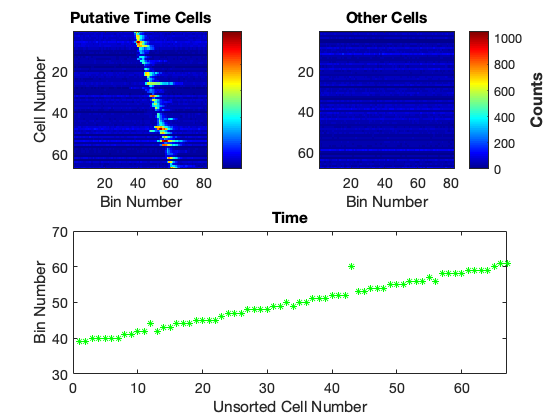

[~, actualT] = max(PSTH(sdo.ptcList,:), [], 2); % Actual Time Vector
figure(9)
clf
subplot(2,2,1)
imagesc(PSTH(sdo.ptcList,:)); % Putative Time Cells
z = colorbar;
set(z,'YTickLabel',({}))
colormap('jet')
%caxis([0 max(max(PSTH(sdo.ptcList,:)))])
title('Putative Time Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Bin Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(2,2,2)
imagesc(PSTH(sdo.ocList,:)); % Other Cells
z = colorbar;
caxis([0 max(max(PSTH(sdo.ptcList,:)))]) % NOTE: setting limits based on the same expected for putative time cells.
ylabel(z,'Counts', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
colormap('jet')
title('Other Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Bin Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% ylabel('Cell Number', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)

subplot(2,2,3:4)
plot(actualT, 'g*')
xlim([0 length(sdo.ptcList)])
%ylim([0 nbins])
title('Time', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Bin Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-2)
set(gca,'FontSize', figureDetails.fontSize-2)

print(['/Users/ananth/Desktop/figs/syntheticData/synthData_PSTH_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)], ...
    '-djpeg')

## Save data

Finally, it is crucial to save not just the dataset but also all the control parameters involved, in one convenient location.

if ops0.saveData == 1
    save([saveFolder db.mouseName '_' db.date '_eventLibrary_2D.mat'], 'eventLibrary_2D')
    save([saveFolder ...
        'synthDATA' ...
        '_tCP' num2str(sdcp.timeCellPercent) ...
        '_cO' lower(sdcp.cellOrder) ...
        '_mHTP' num2str(sdcp.maxHitTrialPercent) ...
        '_hTPA' lower(sdcp.hitTrialPercentAssignment) ...
        '_tO' lower(sdcp.trialOrder) ...
        '_eW' num2str(sdcp.eventWidth{1}) ...
        '_eAF' sdcp.eventAmplificationFactor ...
        '_eT' lower(sdcp.eventTiming) ...
        '_sF' num2str(sdcp.startFrame) ...
        '_eF' num2str(sdcp.endFrame) ...
        '_iFWHM' num2str(sdcp.imprecisionFWHM) ...
        '_iT' lower(sdcp.imprecisionType) ...
        '_n' lower(sdcp.noise) ...
        '_np' num2str(sdcp.noisePercent) ...
        '.mat'], ...
        'sdcp', 'sdo')
end
toc

Elapsed time is 27.229999 seconds.


disp('All done!')

All done!
